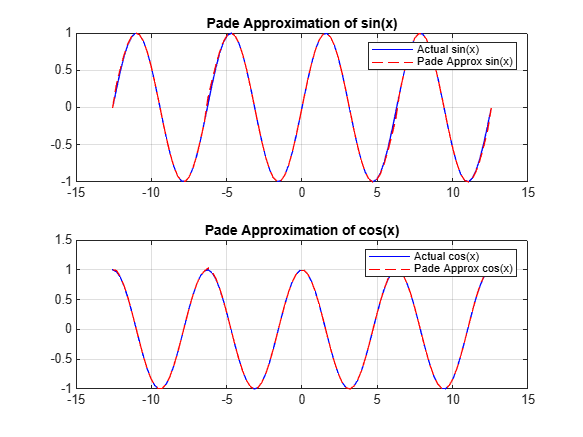

function fAprox = newPade(x, c, m, k)
  if length(c) < m+k+2
      error('< %i c coeficients', m+k+2)
  end

  C = zeros(k);
  y = zeros(k, 1);
  for i = 1:k
    for j = 1:k
      if m+i-j>0
        C(i, j) = c(m+i-j+1);
      end
    end
    y(i) = -c(m+i+1);
  end
  b = C \ y; 

  b = [1; b];

  a = zeros(m+1, 1);
  for j=1:m+1
    for l=1:min(j, k+1)
      a(j) = a(j) + c(j-l+1)*b(l);
    end
  end

  fAproxNumarator = polyval(a(m+1:-1:1), x);
  fAproxNumitor = polyval(b(k+1:-1:1), x);
  fAprox = fAproxNumarator./fAproxNumitor;
end

function [sin] = pade_sin(x, k, m)
    x = rem(x, 2*pi);
    n = k+m+1;
    coefSin = [0, 1];
    coefK = 1;
    for i = 1 : n
        coefK = - coefK * (2 * i) * (2 * i + 1);
        coefSin = [coefSin, 0, 1 / coefK];
    end
    sin = newPade(x, coefSin, m, k);
end

function [cos] = pade_cos(x, k, m)
	x = rem(x, 2*pi);
	n = k+m+1;
	coefCos = [1];
	coefK = 1;
	for i = 1: n
		coefK = - coefK * (2*i);
		coefCos = [coefCos, 0, 1/coefK];
		coefK = coefK * (2*i+1);
	end
	cos = newPade(x, coefCos, m, k);
end

x = linspace(-4*pi, 4*pi, 100);

actual_sin = sin(x);
actual_cos = cos(x);

pade_sin_approx = pade_sin(x, 6, 7);
pade_cos_approx = pade_cos(x, 6, 8);

figure;
subplot(2,1,1);
plot(x, actual_sin, 'b');
hold on;
plot(x, pade_sin_approx, 'r--');
legend('Actual sin(x)', 'Pade Approx sin(x)');
title('Pade Approximation of sin(x)');
grid on;

subplot(2,1,2);
plot(x, actual_cos, 'b');
hold on;
plot(x, pade_cos_approx, 'r--');
legend('Actual cos(x)', 'Pade Approx cos(x)');
title('Pade Approximation of cos(x)');
grid on;


error_cos = cos(pi/3) - pade_cos(pi/3,6,7)

error_cos = 2.4141e-11

error_sin = sin(pi/3) - pade_sin(pi/3,6,8)

error_sin = 1.1282e-12